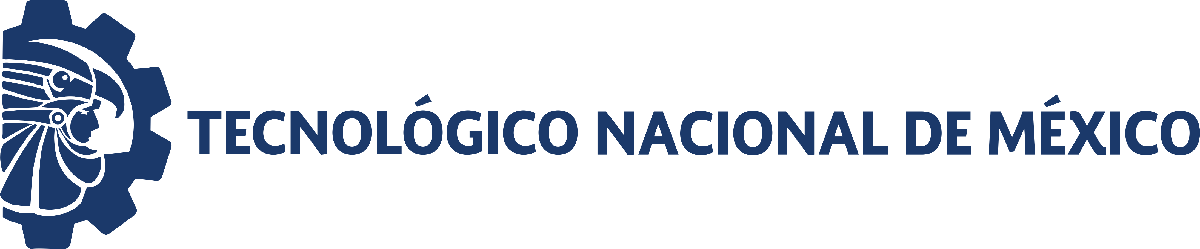                                 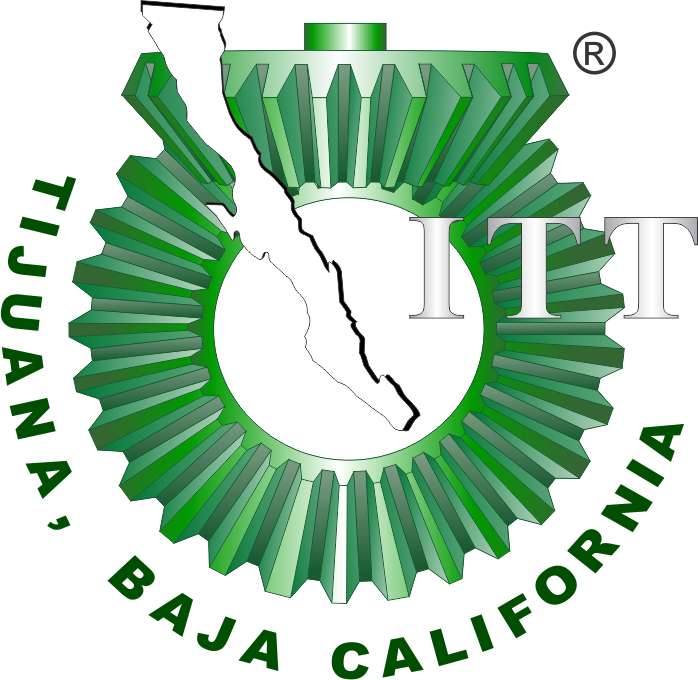

# Práctica 4: Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

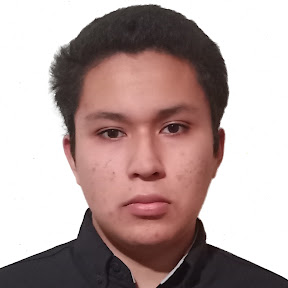

Nombre del alumno: **Ramírez Zepeda Alejandro**

Número de control: **22211765**

Correo institucional: **L22211765@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180; %Tiempo de la simulación en días
dt = 1E-3; %Intervalo de integración para el método de solución por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el método numerico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parámetros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211765; % semilla ára asegurar reproducibilidad
rng (seed, 'twister')
%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmin - xmax).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x1(0) = 
   58.0509   58.3084   58.2271   57.9493   58.1527   57.2640   58.0605   58.2120   57.7471   57.6907



x2(0) = 
   43.2922   43.4842   43.4236   43.2164   43.3681   42.7054   43.2994   43.4124   43.0656   43.0235



x3(0) = 
  870.7642  874.6264  873.4069  869.2398  872.2906  858.9605  870.9079  873.1802  866.2066  865.3599



## Caso: Sin transfusión sanguínea [u(t) = 0]

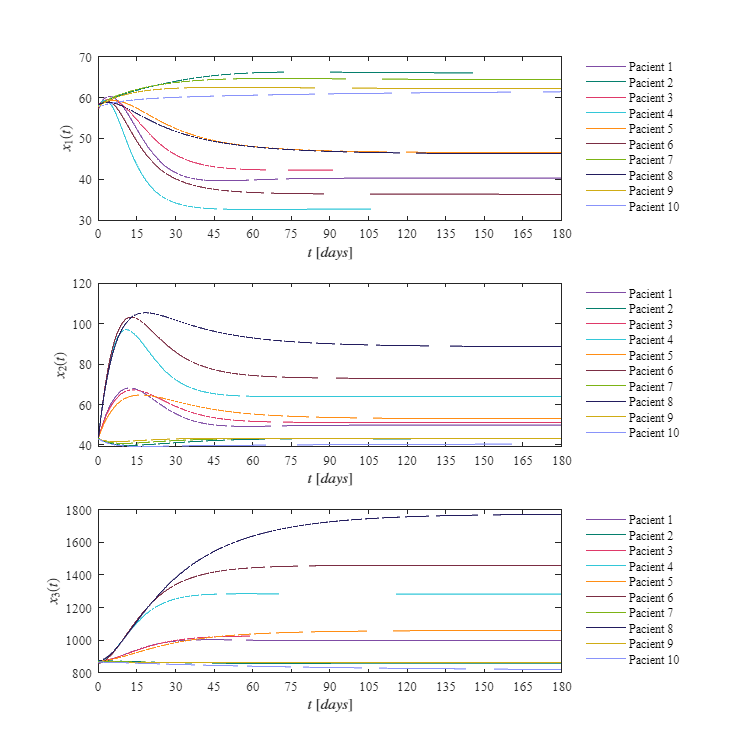

u = zeros(n+1,1); %No hay transfusion
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusión sanguínea [u(t) = 1 [t1,t2]]

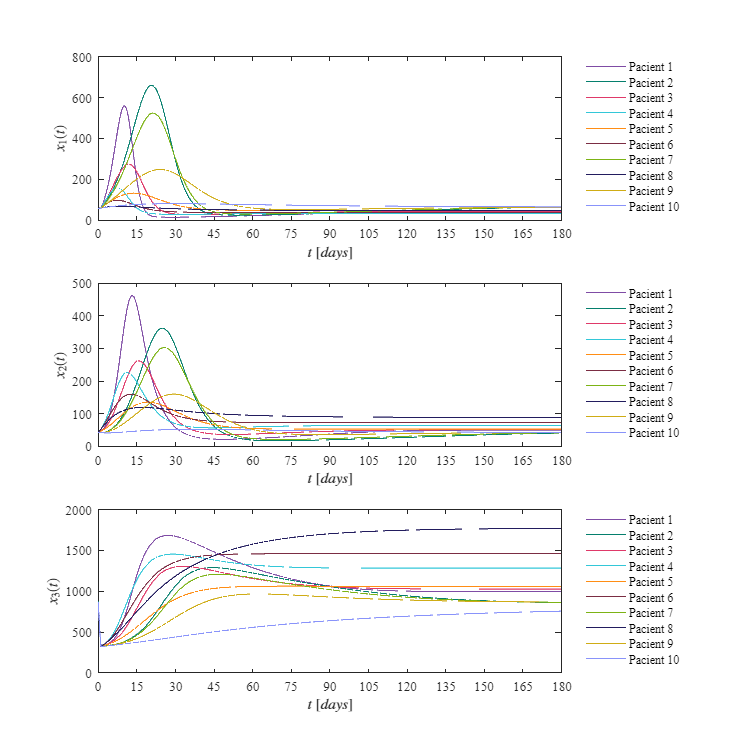

u ((1:1000),1) = 1; %Si hay transfusion
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Función: Modelo matemático


$$\dot{x_1 } =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\dot{x_3 } =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    %Parametros fijos del sistema
    Base = 885.42; x0 = 7.3885; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend);
    n = round(tend/dt);
    x1 = zeros(n+1,1); x1(1) = x1_0;
    x2 = zeros(n+1,1); x2(1) = x2_0;
    x3 = zeros(n+1,1); x3(1) = x3_0;
    
    for i = 1:n %Metodo de Euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(x0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end

## Función: Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])


    mycolors =    [127,76,165;
                5,127,109;
                223,57,105;
                51,199,216;
                255,141,20;
                123,45,67;
                124,179,21;
                34,28,94;
                207,172,21;
                137,147,250]/255;
    colororder(mycolors)

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Pacient 1','Pacient 2','Pacient 3','Pacient 4','Pacient 5',...
            'Pacient 6','Pacient 7','Pacient 8','Pacient 9','Pacient 10');
    set(L,'FontSize', 9,'Box','off','Location','NorthEastOutside');
    set(gca, 'FontName', 'Times New Roman', 'FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Pacient 1','Pacient 2','Pacient 3','Pacient 4','Pacient 5',...
            'Pacient 6','Pacient 7','Pacient 8','Pacient 9','Pacient 10');
    set(L,'FontSize', 9,'Box','off','Location','NorthEastOutside');
    set(gca, 'FontName', 'Times New Roman', 'FontSize',10)

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Pacient 1','Pacient 2','Pacient 3','Pacient 4','Pacient 5',...
            'Pacient 6','Pacient 7','Pacient 8','Pacient 9','Pacient 10');
    set(L,'FontSize', 9,'Box','off','Location','NorthEastOutside');
    set(gca, 'FontName', 'Times New Roman', 'FontSize',10)

    if fig == 1
        exportgraphics(gcf,'Caso sin transfusión.pdf','ContentType','Vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso con transfusión.pdf', 'ContentType','Vector')
    end
end